This script is to illustrate how online adaptation can improve real time prediction. The adaptation algorithm implemented in nonlinear recursive least square, which is equivalent to extended kalman filter. 

First, we specify the system and its gradient w.r.t. to the parameter

% f = @(a,x) a*sin(a*x); % dynamics x(k+1) = f(x(k))
% f_a = @(a,x) sin(a*x)+a*cos(a*x)*x;
% f_x = @(a,x) a^2*cos(a*x);
f = @(a,x) a*x; % dynamics x(k+1) = f(x(k))
f_a = @(a,x) x;
f_x = @(a,x) a;
g1 = @(a,x) f_a(a,x);
g2 = @(a,x) f_a(a, f(a,x)) + f_x(a, f(a,x))*g1(a,x);
g3 = @(a,x) f_a(a, f(a,f(a,x))) + f_x(a, f(a,f(a,x)))*g2(a,x);
g = @(a,x) [g1(a,x), 
    g2(a,x),
    g3(a,x)];

Specification of the time varying parameter

p = @(t) 1+0.05*sin(t/10);

Specify noise level

noise = 0.5;

Initial conditions and ground truth trajectory

x0 = 1; % Initial state
T = 100; % Horizon
x = zeros(T+1,1); x(1) = x0;
a = zeros(1,T);
for t = 1:T+20
    a(t) = p(t);
    x(t+1) = f(a(t),x(t)) + noise*randn;
end

Visualization of the trajectory

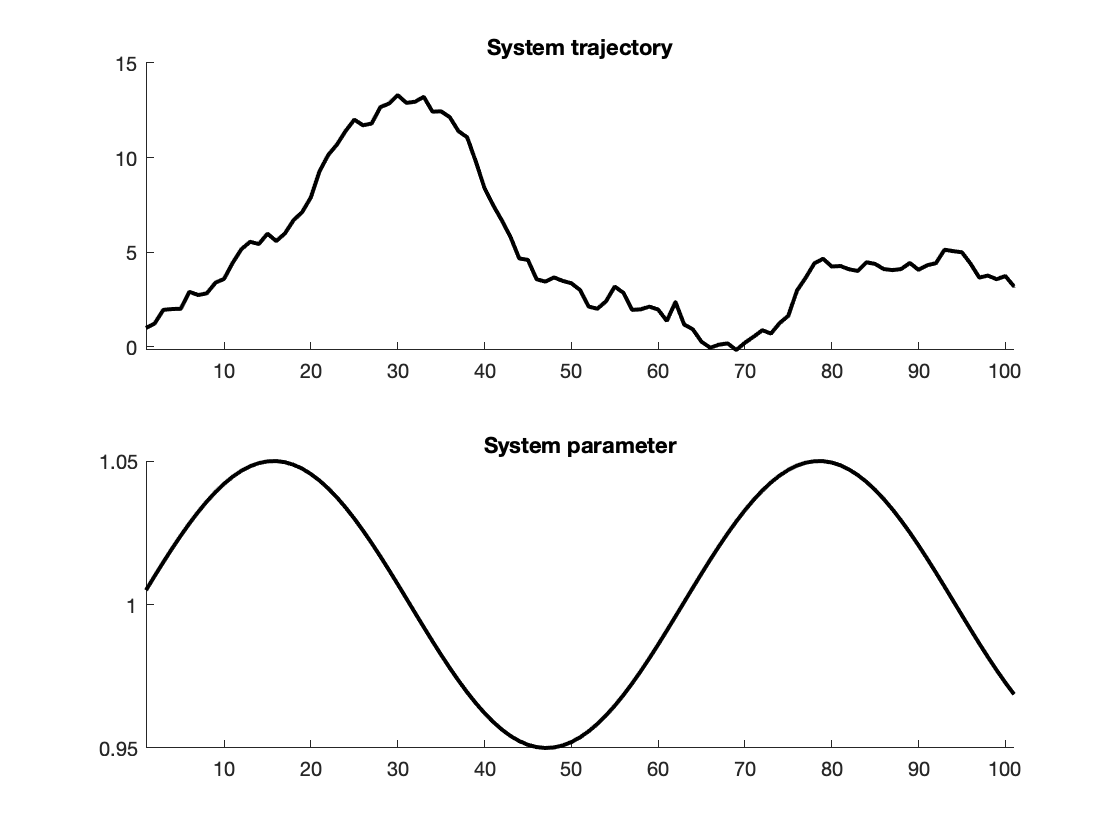

figure; 
subplot(211)
hold on
plot(x, 'k', 'LineWidth', 2)
xlim([1,T+1])
title("System trajectory")
subplot(212)
hold on
plot(a, 'k', 'LineWidth', 2)
xlim([1,T+1])
title("System parameter")

Parameters for trajectory prediction

a0 = 1.5; % Initial estimation of the parameter
h = 3; % Prediction horizon
ADAPT =  true; % Adaptation or not
lambda = 0.4; % Forgetting factor in adaptation
step = 1; % adaptation step
weight = [1, 0.9, 0.8];

Result for trajectory prediction

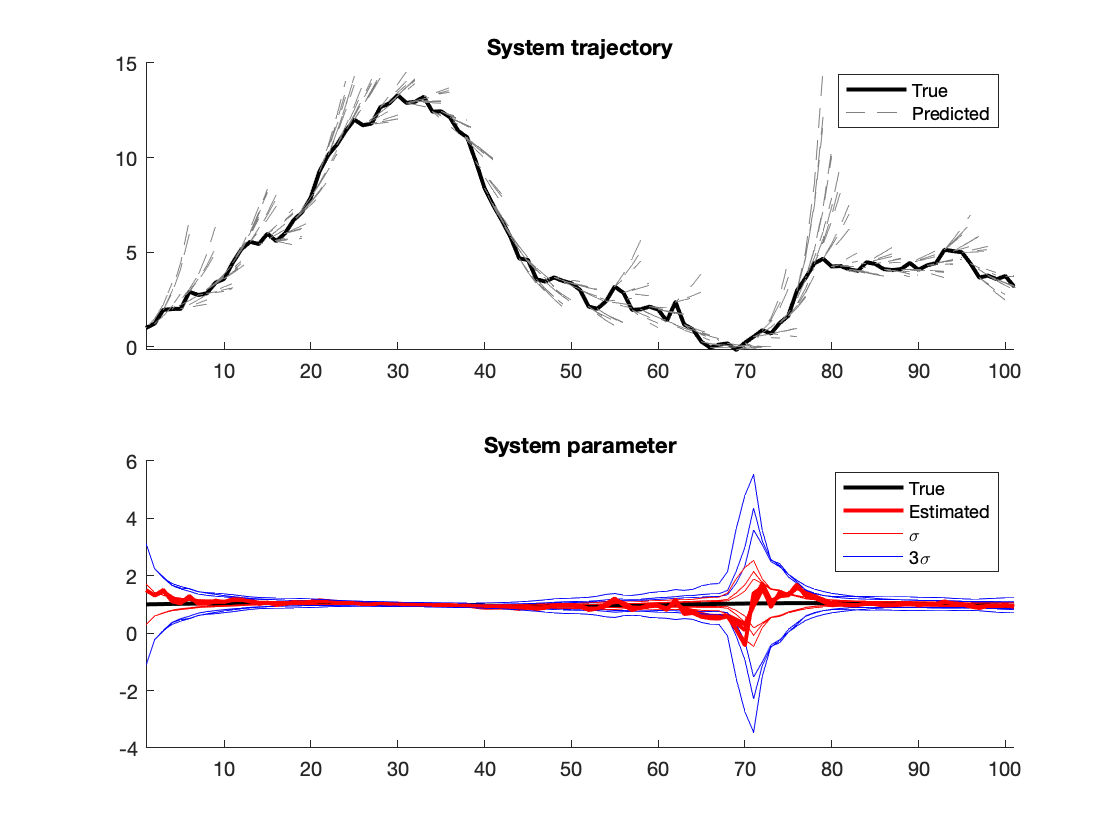

ahat = a0 * ones(1,T+1);
H = ones(1,T+1);
G = zeros(1,step);
e = zeros(1,step);
subplot(211);
error = 0;
Var = 0.5*ones(1, step);
for t = 2:T+1
    xhat = predict(f, ahat(t-1), x(t-1), h);
    error = error + weight * (x(t:t+h-1) - xhat(2:end)).^2;
    if ADAPT
        H(t) = lambda*H(t-1); % inverse of learning gain
        E = 0; % multi-step error
        for i = 1:min([step, t-1])
            xback = predict(f, ahat(t-1), x(t-i), i);
            e(i) = x(t) - xback(end);
            grad = g(ahat(t-1), x(t-i));
            G(i) = grad(i);
            H(t) = H(t) + lambda^(i-1)*G(i)'*G(i)*weight(i);
            E = E + lambda^(i-1)*G(i)'*e(i)*weight(i);
        end
        ahat(t) = ahat(t-1) + inv(H(t))*E;
        F = inv(H(t));
        Var(t) = Var(t-1)*(1-F*x(t-1)^2)^2 + (F*x(t-1))^2*noise^2; %Update variance
    end
    plot(t-1:t+h-1, xhat,'--','color',[0.5,0.5,0.5])
end
legend("True","Predicted")
subplot(212)
plot(ahat,'r','LineWidth',2)
plot(sqrt(Var) + a(1:T+1),'r')
plot(3.*sqrt(Var) + a(1:T+1),'b')
plot(-sqrt(Var) + a(1:T+1),'r')
plot(-3.*sqrt(Var) + a(1:T+1),'b')
xlim([1,T+1])
legend("True","Estimated","\sigma","3\sigma")